# Snow Thickness Analysis

Since we do not have Snow Thickness for all years, I wanted to see if there are any parameters that could capture snow thickness. 

close all
clear all
%Where is your data?
workdir = '~/Documents/git_Research/Permafrost_ERRA/Permafrost_ERRA/datERRA/UK_years';

cd(workdir)
load('Considered_VarParameters.mat');
%Where do you want to save files?
workdirfig = '~/Documents/git_research/Permafrost_ERRA/Permafrost_ERRA/datERRA/UK_years/figures/';


We do not have consistent Snow Depth Data, so lets see if Spring Discharge Max is telling enough of Max Snow Depth. 

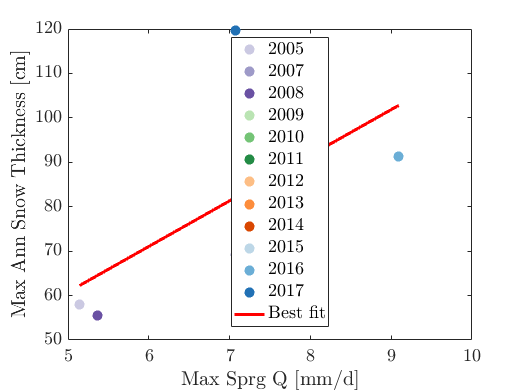

f1 = figure; 
 yearsplots(Q_max_april_june,SD_max,years,VarParameters_Names{5},VarParameters_Names{6},'',1,1)


  cd(workdirfig);
  % set printing options
  str       = {'MaxSprngQ_SnowThickness' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');

It seems that there is a correlation between Max Snow Depth and Max Spring Discharge Rate. Maybe total Q - P for Spring vs Max Snow Depth is more correlated?

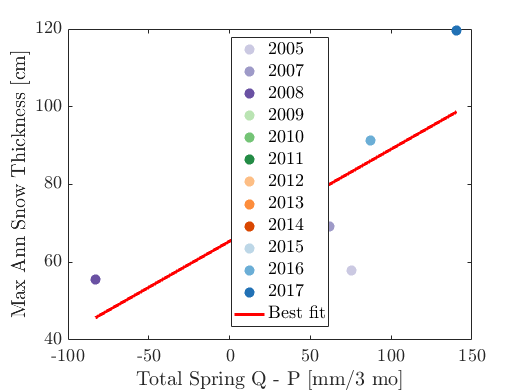

 f1 = figure; 
 yearsplots(Q_total_april_june - P_total_april_june, SD_max,years, 'Total Spring Q - P [mm/3 mo]', VarParameters_Names{6},'',1,1)
   cd(workdirfig);
  % set printing options
  str       = {'MaxSprngQ-P_SnowThickness' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');

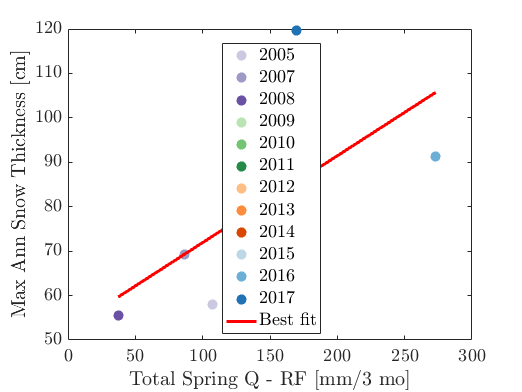


   f1 = figure; 
 yearsplots(Q_total_april_june - RF_total_april_june, SD_max,years, 'Total Spring Q - RF [mm/3 mo]', VarParameters_Names{6},'',1,1)
   cd(workdirfig);
  % set printing options
  str       = {'MaxSprngQ-RF_SnowThickness' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');

It seems that Max Spring Discharge, Total Spring Discharge excluding total spring precipitation and total spring discharge excluding spring rainfall are positively correlated with max annual snow thickness.  